clear; close all; clc

# Fourier Transform Toy Example

**Code Authored By**: Shawhin Talebi

### Define signal

% function to define signal
f = @(x) sin(x)+sin(2*x);

Fs = 10000;     % sample rate
numPeriods = 7; % number of periods of signal
x = linspace(0,2*pi*numPeriods,Fs*numPeriods); % domain of signal

% define signal
y = f(x);

### Perform FFT

x = fft(y);

### Compute 1-sided Power Spectrum

% get length of signal
L = length(y);
% convert indicies to frequency values
k = Fs*(0:(L/2))/L;

% calculate constituent frequency contributions. We don't care about
% coefficent sign (+/-) only magnitude
P2 = abs(x/L);

% 2-sided spectrum has both positive and negative frequency values, we can
% convert it to a 1-sided spectrum with only positive frequency values by
% doubling positive frequnecy coefficents in 2-sided spectrum
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

### Plot Signal and Spectrum

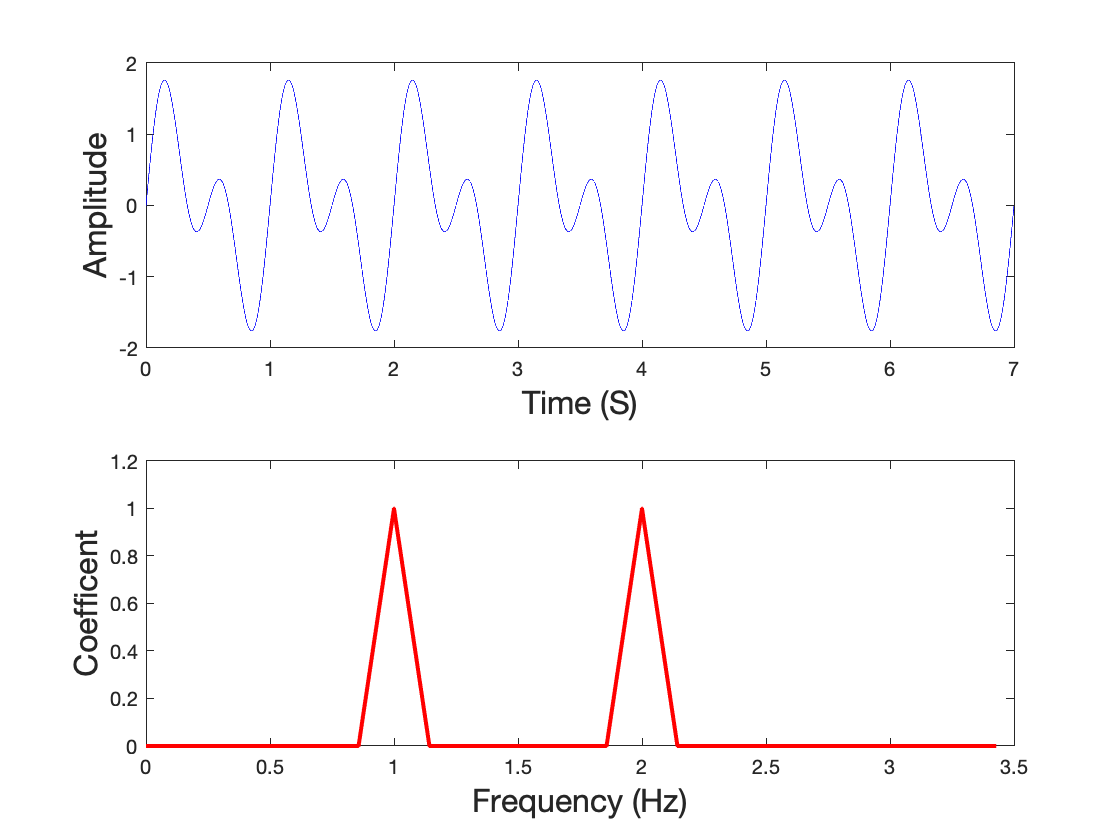

% plot original signal
subplot(2,1,1)
t = ((1:L)-1)/Fs;
plot(t, y, 'b-')

% format time domain plot
ax=gca;
ax.XLabel.String = 'Time (S)';
ax.XLabel.FontSize = 16;
ax.YLabel.String = 'Amplitude';
ax.YLabel.FontSize = 16;

% plot signal in frequency domain
subplot(2,1,2)
plot(k(1:25),P1(1:25),'r-', 'LineWidth', 2);

% format frequency domain plot
ax=gca;
ax.XLabel.String = 'Frequency (Hz)';
ax.XLabel.FontSize = 16;
ax.YLabel.String = 'Coefficent';
ax.YLabel.FontSize = 16;

% print figure to file
print('ft_toy_exmaple', '-dpng');